Parâmetros

R = 0.179 %[ohm]

R = 0.1790

L = 0.0456 %[mH]

L = 0.0456

J = 35.1 %[gcm2]

J = 35.1000

c = 11.9 %[rpm/mNm]

c = 11.9000

kt = 12 %[mNm/A]

kt = 12

kv = 797 %[rpm/V]

kv = 797

ke = 1/kv %[V/rpm]

ke = 0.0013

Espaços de Estado

A = [-R/L -ke/L; kt/J -c/J]

A =    -3.9254   -0.0275
    0.3419   -0.3390


B = [1/L 0; 0 -1/J]

B =    21.9298         0
         0   -0.0285


C = [1 0; 0 1]

C =      1     0
     0     1


D = zeros(2)

D =      0     0
     0     0



model = ss(A,B,C,D) 

model =
 
  A = 
             x1        x2
   x1    -3.925  -0.02752
   x2    0.3419    -0.339
 
  B = 
             u1        u2
   x1     21.93         0
   x2         0  -0.02849
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


Entradas

Va = 10*ones(10000,1)

Va =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10



tau = 0.091*([zeros(5000,1);ones(5000,1)])

tau =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



time = linspace(0,20,10000)'

time =          0
    0.0020
    0.0040
    0.0060
    0.0080
    0.0100
    0.0120
    0.0140
    0.0160
    0.0180


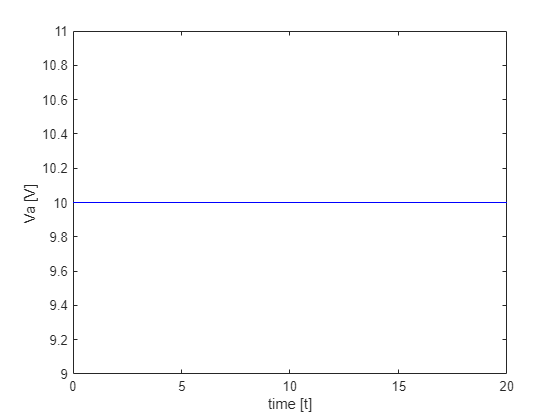


plot(time,Va,'-b')
xlabel("time [t]")
ylabel("Va [V]")

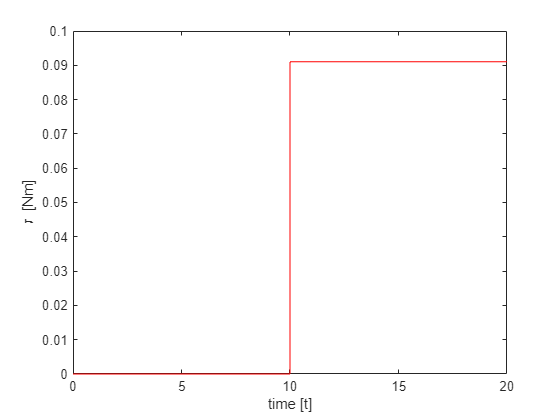


plot(time,tau,'-r')
xlabel("time [t]")
ylabel("\tau [Nm]")

Respostas

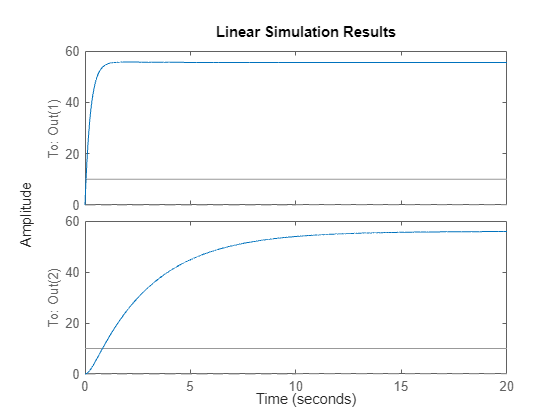

lsim(model,[Va tau],time)